Problem 1

1a.

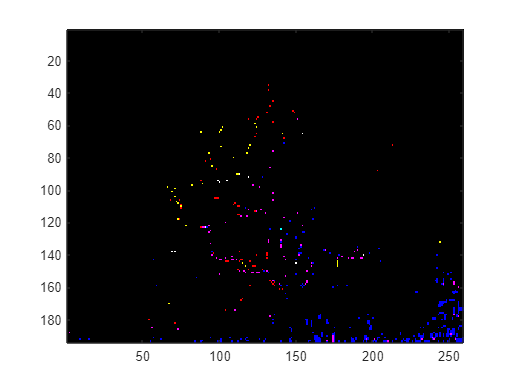

im1 = imread('Tree1.jpg');
imagesc(~im1);
colormap gray;

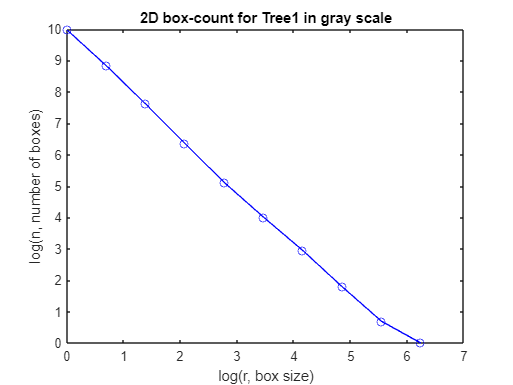

th = (im1 < 125);
[n,r] = boxcount(th);
plot(log(r), log(n), 'bo-');
xlabel('log(r, box size)');
ylabel('log(n, number of boxes)');
title('2D box-count for Tree1 in gray scale')

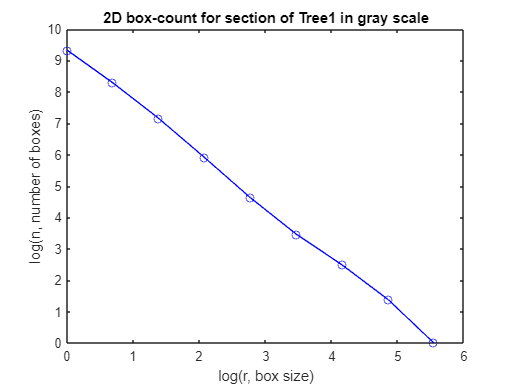


i = th(20:160, 25:240, 3);
[n1,r1] = boxcount(i);
plot(log(r1), log(n1), 'bo-');
xlabel('log(r, box size)');
ylabel('log(n, number of boxes)');
title('2D box-count for section of Tree1 in gray scale')

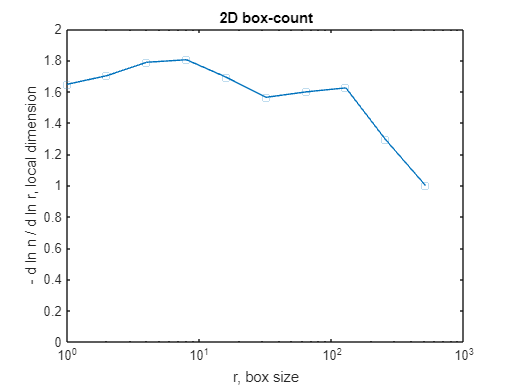


boxcount(th, 'slope');

pf = polyfit(log(r'), log(n'), 1);
disp(pf);

   -1.6363    9.8354



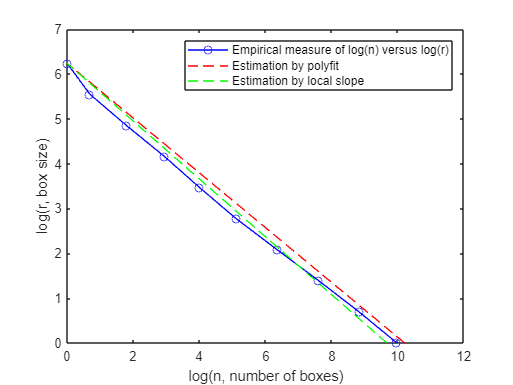

plot(log(n), log(r), 'bo-', log((r/r(end)).^(-1.6363)), log(r), 'r--', log((r/r(end)).^(-1.55)), log(r), 'g--')
ylabel('log(r, box size)');
xlabel('log(n, number of boxes)');
legend('Empirical measure of log(n) versus log(r)','Estimation by polyfit','Estimation by local slope')

pf1 = polyfit(log(r), log(n), 1);
disp(pf1(1));

   -1.6363



1b. The slope of the 1st degree linear polynomial fit is -1.6363, while the local slope is -1.55 at the most stable box size. Meanwhile, the slope of the boxcount output is -1.6363.

1c. Although technically the slope estimated from 1st degree linear polynimal fit is exactly the same as the empirical slope, based on the graph, the local slope is a better estimation. The local slope maps better onto the empirical slope, and the slope from polyfit seems to be off by a bit. This data makes sense, as the local slope estimation is simply a subsection of the actual data. Meanwhile, the polyfit estimation is simply a rough estimate using a linear fit, which may not always be accurate.

Problem 2

2a.

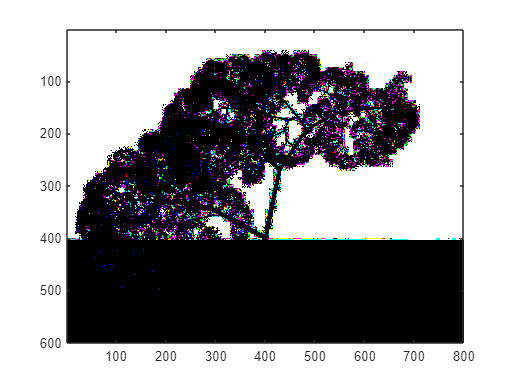

im2 = imread('Tree2.jpg');
imagesc(~im2);
colormap gray;

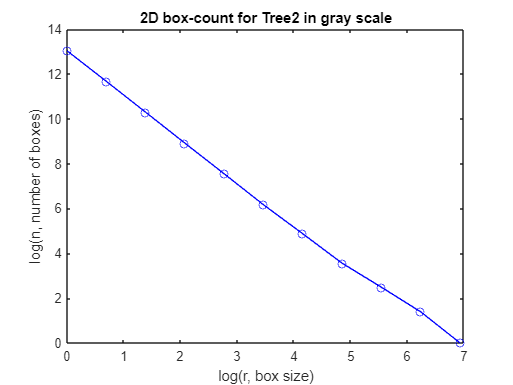

th = (im2 < 125);
[n,r] = boxcount(th);
plot(log(r), log(n), 'bo-');
xlabel('log(r, box size)');
ylabel('log(n, number of boxes)');
title('2D box-count for Tree2 in gray scale')

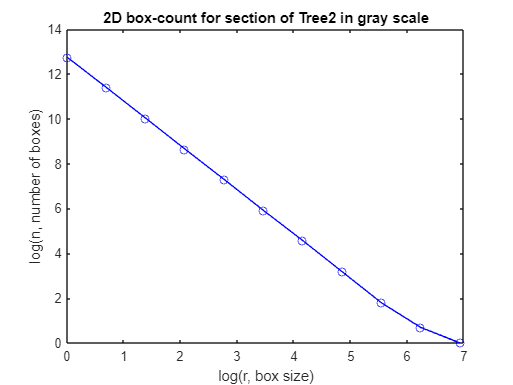


i = th(50:550, 25:750, 3);
[n1,r1] = boxcount(i);
plot(log(r1), log(n1), 'bo-');
xlabel('log(r, box size)');
ylabel('log(n, number of boxes)');
title('2D box-count for section of Tree2 in gray scale')

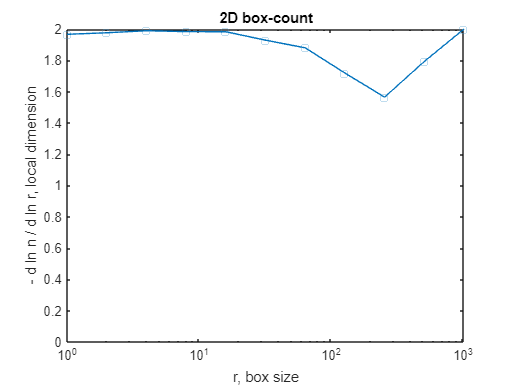


boxcount(th, 'slope');

pf = polyfit(log(r'), log(n'), 1);
disp(pf);

   -1.8764   12.8571



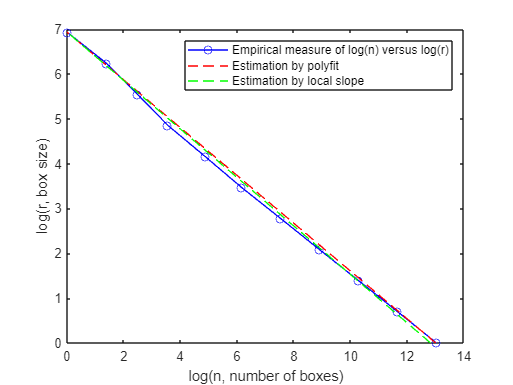

plot(log(n), log(r), 'bo-', log((r/r(end)).^(-1.8764)), log(r), 'r--', log((r/r(end)).^(-1.85)), log(r), 'g--')
ylabel('log(r, box size)');
xlabel('log(n, number of boxes)');
legend('Empirical measure of log(n) versus log(r)','Estimation by polyfit','Estimation by local slope')

pf1 = polyfit(log(r), log(n), 1);
disp(pf1(1));

   -1.8764



2b. The slope of the 1st degree linear polynomial fit is -1.8764, while the local slope is -1.85 at the most stable box size. Meanwhile, the slope of the boxcount output is -1.8764.

2c. Although technically the slope estimated from 1st degree linear polynimal fit is exactly the same as the empirical slope, based on the graph, the local slope is a slightly better estimation. The local slope maps better onto the empirical slope, and the slope from polyfit seems to be off by a bit. This data makes sense, as the local slope estimation is simply a subsection of the actual data. Meanwhile, the polyfit estimation is simply a rough estimate using a linear fit, which may not always be accurate. Overall, both slopes seem to be a good estimate of the empirical slope, but the local slope is generally better since it is derived from the actual data.

Problem 3

3a.

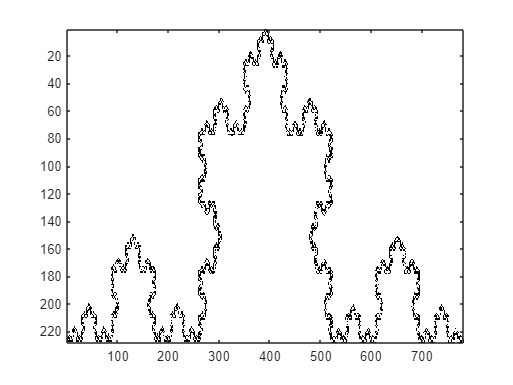

im3 = imread('big_Koch.png');
imagesc(~im3);
colormap gray;

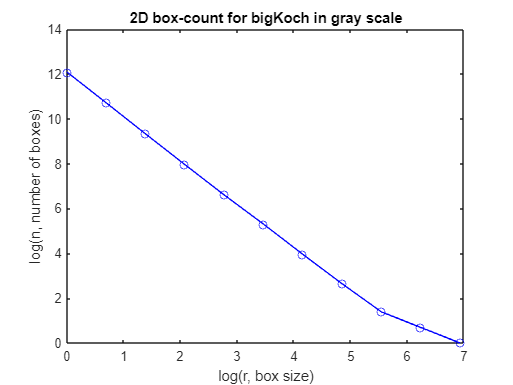

th = (im3 < 125);
[n,r] = boxcount(th);
plot(log(r), log(n), 'bo-');
xlabel('log(r, box size)');
ylabel('log(n, number of boxes)');
title('2D box-count for bigKoch in gray scale')

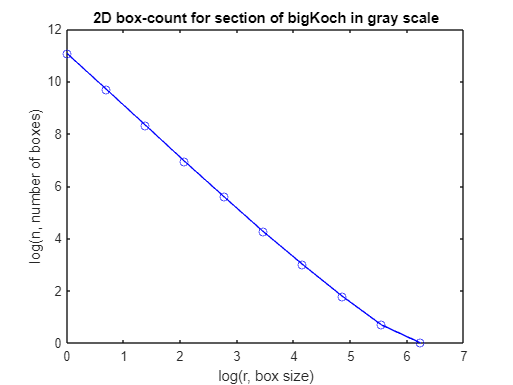


i = th(5:220, 250:550, 3);
[n1,r1] = boxcount(i);
plot(log(r1), log(n1), 'bo-');
xlabel('log(r, box size)');
ylabel('log(n, number of boxes)');
title('2D box-count for section of bigKoch in gray scale')

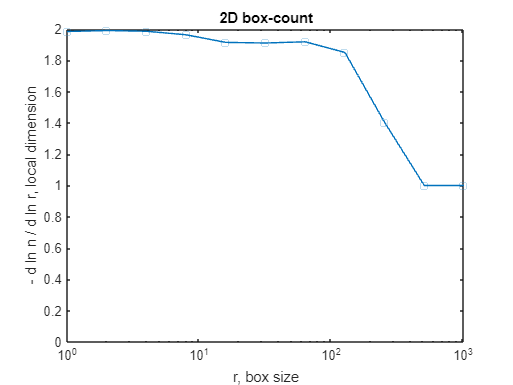


boxcount(th, 'slope');

pf = polyfit(log(r'), log(n'), 1);
disp(pf);

   -1.8037   11.7627



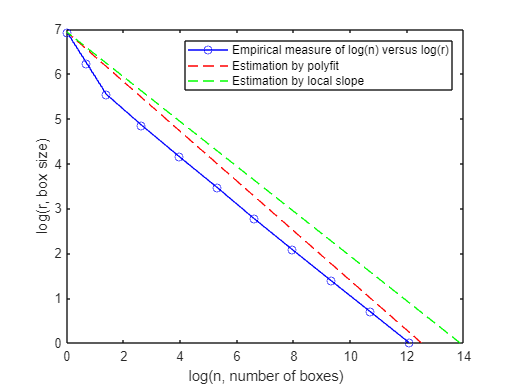

plot(log(n), log(r), 'bo-', log((r/r(end)).^(-1.8037)), log(r), 'r--', log((r/r(end)).^(-2)), log(r), 'g--');
ylabel('log(r, box size)');
xlabel('log(n, number of boxes)');
legend('Empirical measure of log(n) versus log(r)','Estimation by polyfit','Estimation by local slope')

pf1 = polyfit(log(r), log(n), 1);
disp(pf1(1));

   -1.8037



3b. The slope of the 1st degree linear polynomial fit is -1.8037, while the local slope is -2 at the most stable box size. Meanwhile, the slope of the boxcount output is -1.8037.

3c. Based on the graph, the estimation by polyfit is slightly better than the estimation by local slope. Although both lines do not map on well to the empirical measurement, the polyfit estimation is closer to the empirical slope compared to the local slope estimation, making the polyfit slope slightly better. This is due to the fact that the box count for local slope is pretty unstable, so it is difficult to find a box size where the slope is stable.